%importing data
clear 
%pos is malignant, neg is benign
wdbc = importdata('wdbc.data');
negData = wdbc.data(char(wdbc.textdata(:,2))=='B',:);
posData = wdbc.data(char(wdbc.textdata(:,2))=='M',:);

[posRow, ~] = size(posData);
[negRow, ~] = size(negData);

%splitting into trainging data and test data
pos80 = round(0.8*posRow);
neg80 = round(0.8*negRow);

posTrain = posData(1:pos80, :);
negTrain = negData(1:neg80, :);

%getting prior probabilities from ratios in training data
pos_prior = pos80/(pos80+neg80);
neg_prior = neg80/(pos80+neg80);

posTest = posData(pos80+1:posRow, :);
negTest = negData(neg80+1:negRow, :);
close all 

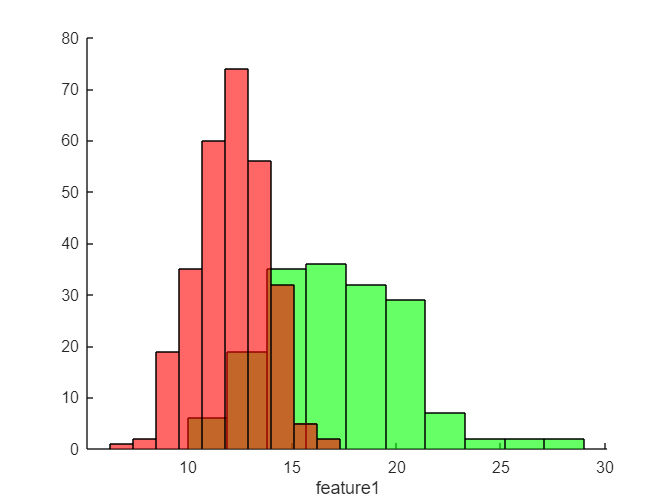

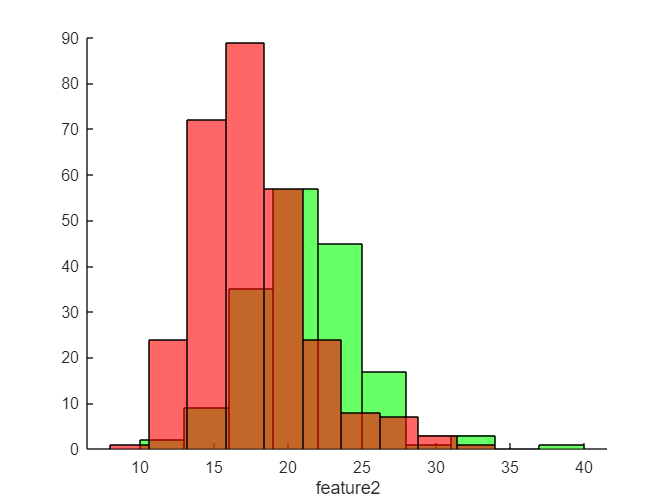

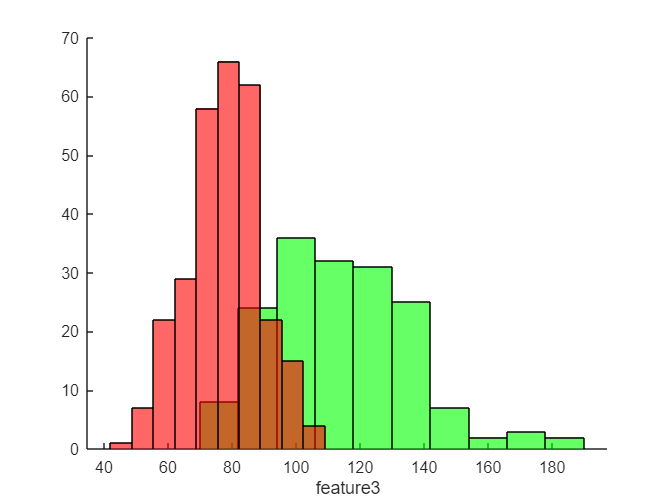

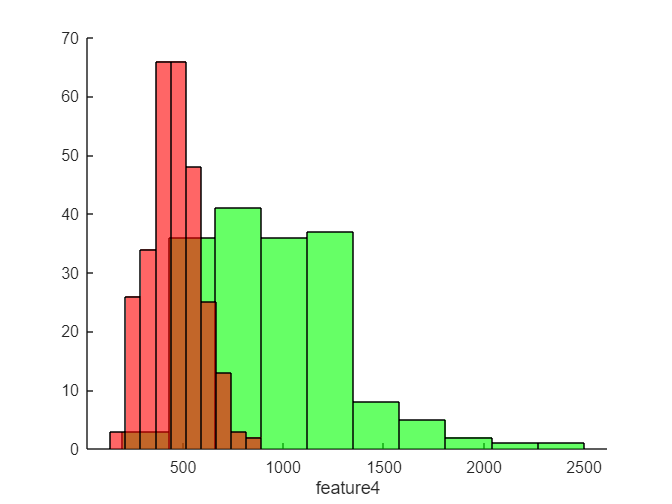

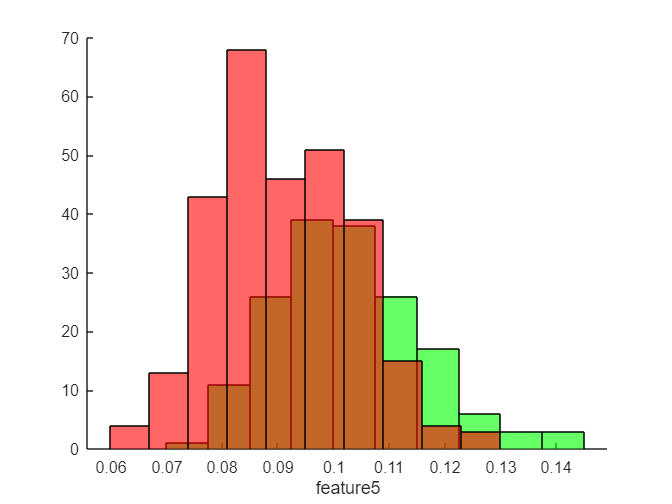

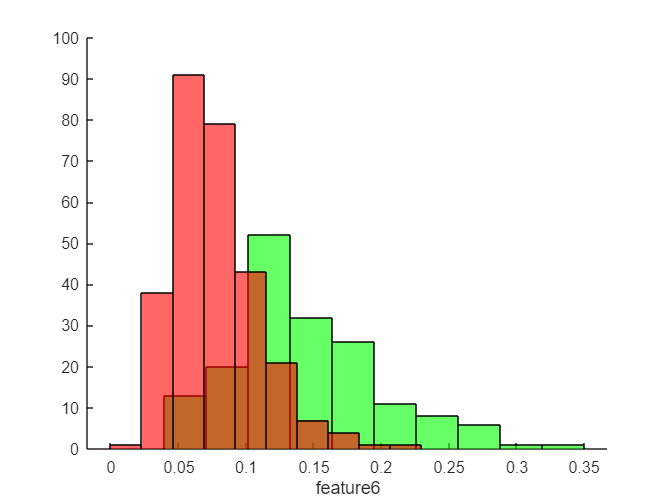

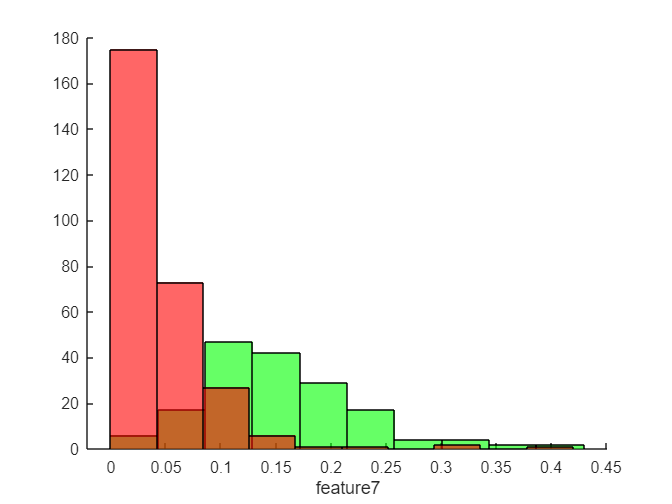

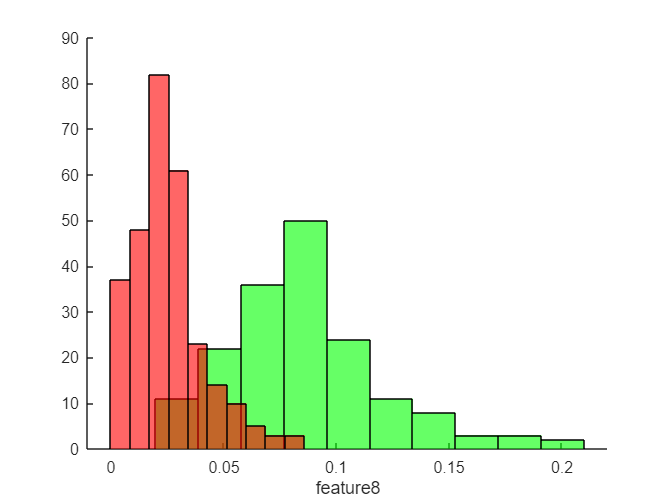

for i = 1:30
    figure
    hold on
    histogram(posTrain(:,i), 10, 'FaceColor', 'g')
    histogram(negTrain(:,i), 10, 'FaceColor', 'r')
    xlabel(['feature' num2str(i)])
    hold off
end

%ones that we like: 28, 23, 21ish, 8, 3

%trying to use features 8 and 28 
%make bayesian characteristics mu and sigma
pos_feat = [posTrain(:,8) posTrain(:,28)];
neg_feat = [negTrain(:,8) negTrain(:,28)];

mu_pos = mean(pos_feat)';
mu_neg = mean(neg_feat)';
cov_pos = cov(pos_feat);
cov_neg = cov(neg_feat);

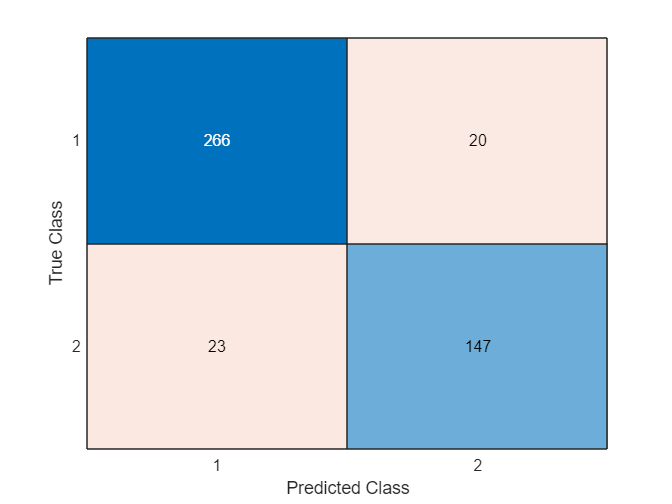

correct = 0;
Y = [ones(size(pos_feat, 1), 1); zeros(size(neg_feat, 1), 1)];
predict = [zeros(size(Y, 1), 1)];
X = [pos_feat; neg_feat];
for i = 1:size(X, 1)
    x = X(i,:)';
    y = Y(i);
    g1_result = g(x, mu_pos, cov_pos, pos_prior);
    g2_result = g(x, mu_neg, cov_neg, neg_prior);
    predict(i) = g1_result - g2_result > 0;
    %correct = correct + ((g1_result - g2_result > 0) == y);
end

C = confusionmat(Y, predict);
confusionchart(C);

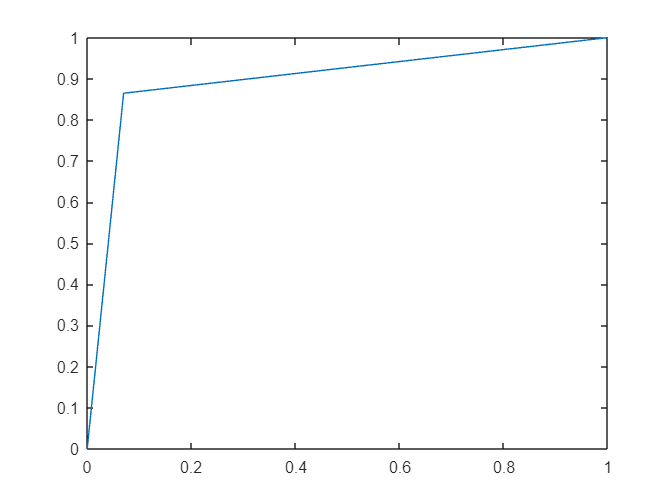

[ex,why] = perfcurve(Y,predict,1);
plot(ex, why)

% acc = correct / size(X, 1);
% fprintf("Accuracy: %.2f\n", acc);

function result = g(x, mean, cov, P)
    cov_i = inv(cov);
    W = -0.5 * cov_i;
    w = cov_i * mean;
    w0 = -0.5 * (mean' * cov_i * mean) - 0.5 * log(det(cov)) + log(P);
    result = x'*W*x + w'*x + w0;
end